# DeconvolutionLab2 pruebas

javaaddpath([matlabroot filesep 'java' filesep 'DeconvolutionLab_2.jar']);

_________________________________________________________________________________________________

## Test Image

testimg = tiffreadVolume("ImagenesEmpleadas3D/simple_3d_ball_blurred.tif");
testpsf = tiffreadVolume("ImagenesEmpleadas3D/simple_3d_psf.tif");

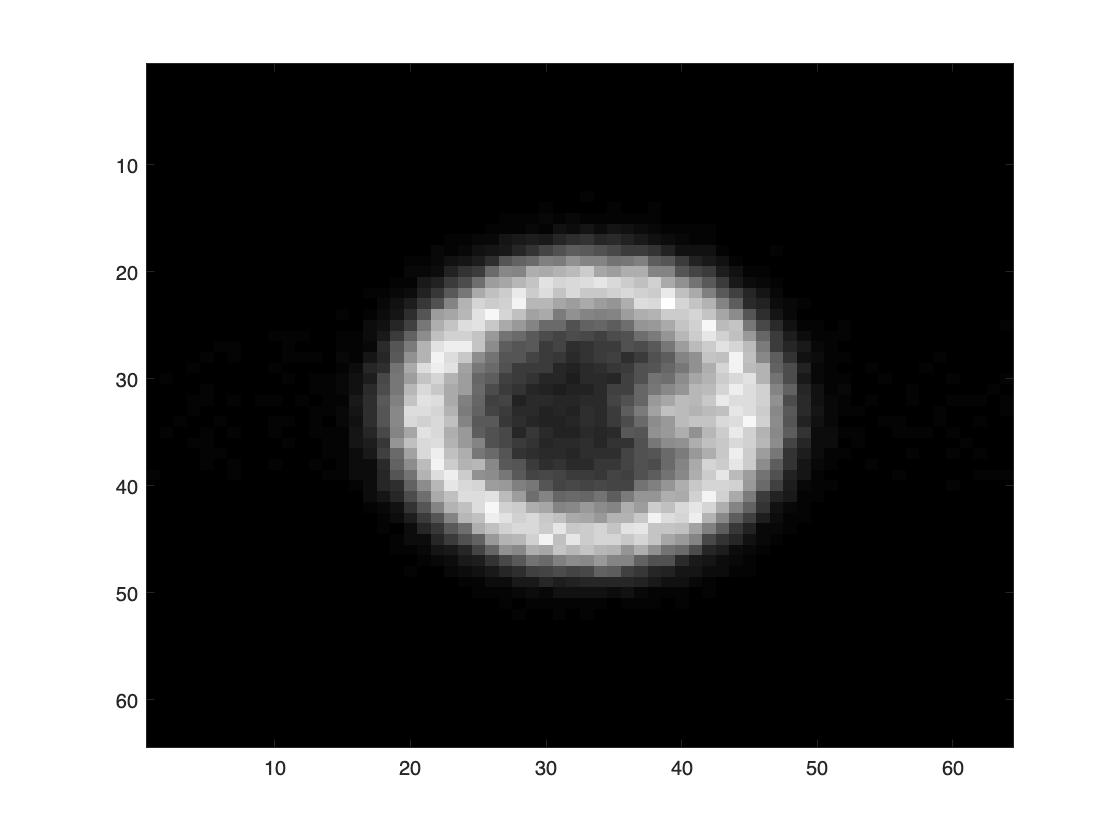

figure();
imagesc(testimg(:,:,30));
colormap gray;

testresult = DL2.RL(testimg, testpsf, 30,'-out stack');

Log   	 326,08 us 	  444,6Mb  	 DeconvolutionLab2 2.1.2 (27.06.2018) on Matlab
Log   	 1282,50 us 	  139,9Mb  	 AcademicFFT Added
Log   	 8,73 ms 	  141,2Mb  	 JTransforms not found
Log   	 35,57 ms 	  150,4Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/FFTW/
Log   	 38,28 ms 	  150,4Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024b.app/java/
Log   	 44,22 ms 	  151,7Mb  	 FFTW Widsom not found in : /Users/yi/FFTW/
Log   	 45,00 ms 	  151,7Mb  	 FFTW Widsom not found in : /Users/yi/
Log   	 45,38 ms 	  151,7Mb  	 FFTW not found
Log   	 8,50 us 	  160,3Mb  	 Create Live Real Signal 


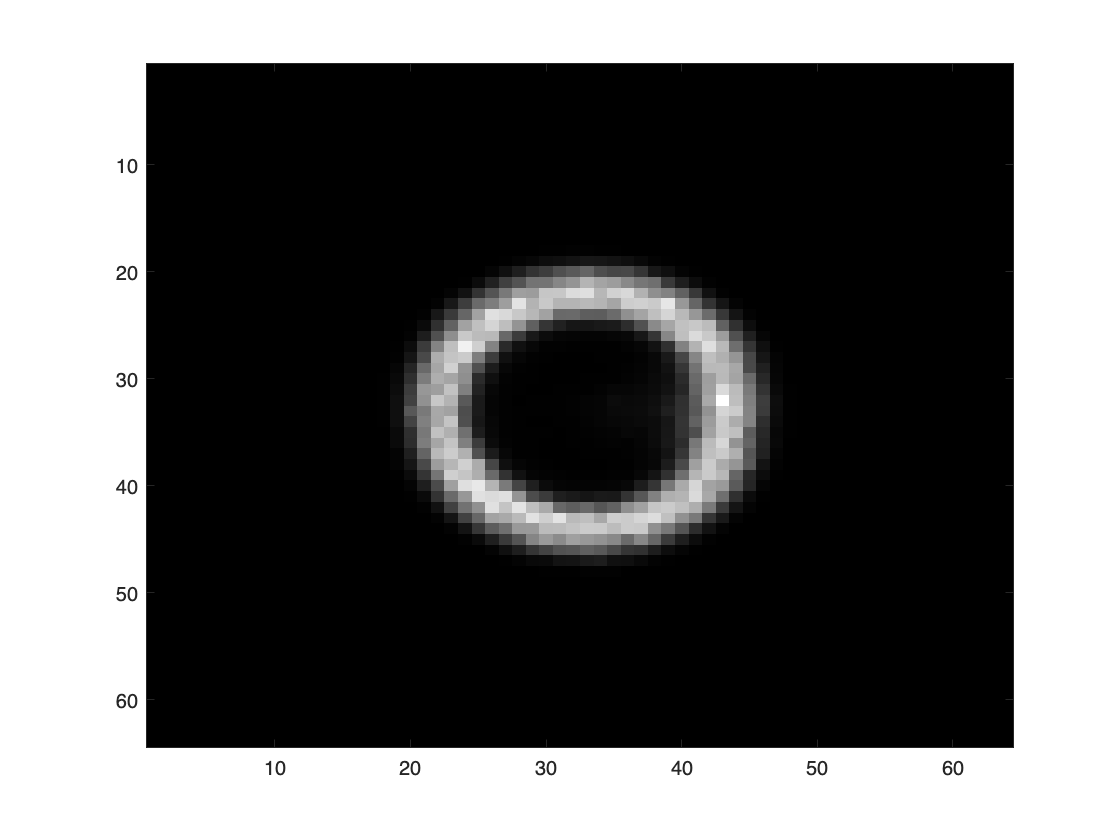

figure;
imagesc(testresult(:,:,30));
colormap gray;

## @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_test_3D.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_test = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    testresult = DL2.RL(testimg, testpsf, 30,'-out');  % Ejecutar deconvolución
    T_test(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_test(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_test(i));
end

Iteración 1: 4.987 s
Iteración 2: 4.896 s
Iteración 3: 4.663 s
Iteración 4: 4.695 s
Iteración 5: 4.641 s
Iteración 6: 4.610 s
Iteración 7: 4.587 s
Iteración 8: 4.577 s
Iteración 9: 4.526 s
Iteración 10: 4.650 s


medianTime_test = median(T_test);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime_test);

Tiempo mediano de deconvolución: 4.646 s


_________________________________________________________________________________________________

## Cells 3D

cellimg = tiffreadVolume("ImagenesEmpleadas3D/3Dconvolved_cell.tif");
cellpsf = tiffreadVolume("ImagenesEmpleadas3D/3Dconvolved_cell_psf.tif");


cellresult = DL2.RL(cellimg, cellpsf, 30,'-out stack');

Log   	 82,00 us 	  333,6Mb  	 Create Live Real Signal 


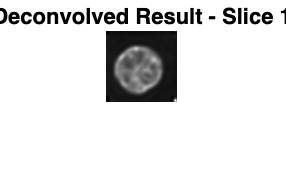

figure;
imshow(cellresult(:,:,35), []);
title('Deconvolved Result - Slice 1');

## @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_cell_3D.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_cell = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    cellresult = DL2.RL(cellimg, cellpsf, 30,'-out');  % Ejecutar deconvolución
    T_cell(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_cell(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_cell(i));
end

Iteración 1: 6.652 s
Iteración 2: 6.662 s
Iteración 3: 6.572 s
Iteración 4: 7.264 s
Iteración 5: 6.616 s
Iteración 6: 6.599 s
Iteración 7: 6.701 s
Iteración 8: 6.596 s
Iteración 9: 6.611 s
Iteración 10: 6.612 s


medianTime_cell = median(T_cell);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime_cell);

Tiempo mediano de deconvolución: 6.614 s


_________________________________________________________________________________________________

## Cube of Spherical Beads

img = tiffreadVolume('ImagenesEmpleadas3D/cube_convolved.tif');
img_b = tiffreadVolume('ImagenesEmpleadas3D/cube_psf.tif');

result_cube_3d = DL2.RL(img, img_b, 30,'-out stack');

Log   	 82,92 us 	 1196,0Mb  	 Create Live Real Signal 


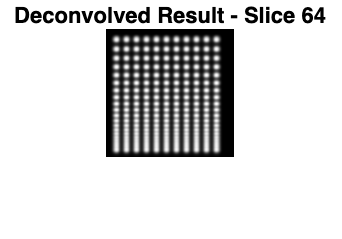

figure;
imshow(result_cube_3d(:,:,30), []);
title('Deconvolved Result - Slice 64');

## @ BENCHMARK

% ------------------------------
% Configuración
% ------------------------------
numIter = 10;                           % Número de ejecuciones
csvFile = 'RL_times_cube_3D.csv';               % Nombre del CSV de salida

% Eliminar archivo previo si existe
if exist(csvFile, 'file')
    delete(csvFile);
end

% ------------------------------
% Bucle de ejecución
% ------------------------------
T_cube = zeros(numIter,1);  % Vector para guardar tiempos

for i = 1:numIter
    tic
    result_cube_3d = DL2.RL(img, img_b, 30,'-out');  % Ejecutar deconvolución
    T_cube(i) = toc;  % Guardar tiempo total
    
    % Guardar inmediatamente en CSV
    writematrix(T_cube(i), csvFile, 'WriteMode', 'append');
    
    fprintf('Iteración %d: %.3f s\n', i, T_cube(i));
end

Iteración 1: 35.237 s
Iteración 2: 35.875 s
Iteración 3: 36.823 s
Iteración 4: 36.509 s
Iteración 5: 36.392 s
Iteración 6: 36.115 s
Iteración 7: 35.712 s
Iteración 8: 35.876 s
Iteración 9: 36.501 s
Iteración 10: 36.236 s



medianTime_cube = median(T_cube);
fprintf('Tiempo mediano de deconvolución: %.3f s\n', medianTime_cube);

Tiempo mediano de deconvolución: 36.176 s


_________________________________________________________________________________________________

## C. Elegans Embryo

function image_stack = load_image_stack(folder_path)
    % Listar todos los archivos en la carpeta y ordenar
    files = dir(fullfile(folder_path, '*.tif'));
    files = [files; dir(fullfile(folder_path, '*.png'))];
    files = [files; dir(fullfile(folder_path, '*.jpg'))];
    [~, index] = sort({files.name});
    files = files(index);
    
    % Leer la primera imagen para obtener las dimensiones
    first_image = imread(fullfile(folder_path, files(1).name));
    [height, width] = size(first_image);
    
    % Crear una matriz 3D vacía para almacenar las imágenes
    image_stack = zeros(height, width, length(files), class(first_image));
    
    % Cargar cada imagen en la matriz 3D
    for i = 1:length(files)
        image_stack(:, :, i) = imread(fullfile(folder_path, files(i).name));
    end
end

### Canal 1

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath1 = '/Users/yi/TFGNotebook/CElegans-CY3';
psfPath1 = '/Users/yi/TFGNotebook/PSF-CElegans-CY3';

% Cargar las imágenes en una matriz 3D
image_stack1 = load_image_stack(imagePath1);
psf_stack1 = load_image_stack(psfPath1);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack1 = image_stack1(1:356, 1:336, :);
psf_stack1 = psf_stack1(179:534,169:504, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack1));

   356   336   104



disp(size(psf_stack1));

   356   336   104



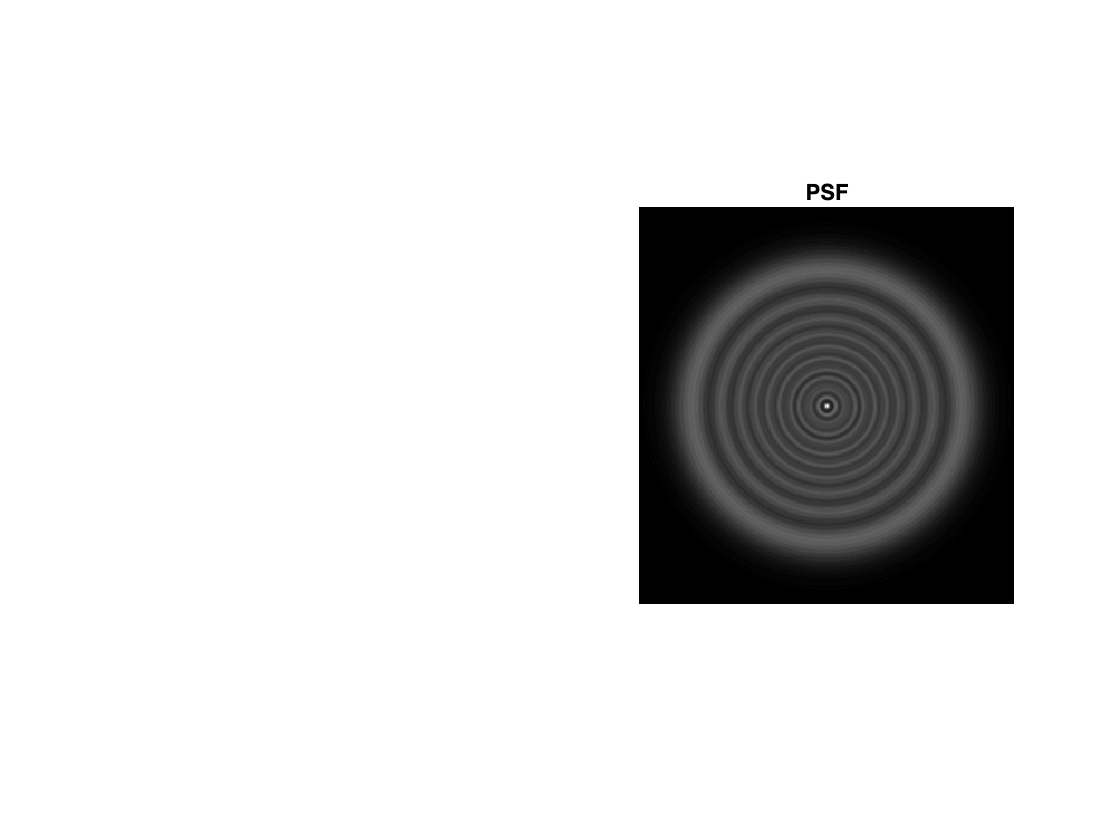

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack1(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel1 = DL2.RL(image_stack1, psf_stack1, 50,'-out stack');

Log   	 73,38 us 	  266,9Mb  	 Create Live Real Signal 


Index in position 3 exceeds array bounds. Index must not exceed 104.

Error in test3D_DL2>plot_orthogonal_views (line 26)
    slice_yz = squeeze(volume3d(:, :, x_center));   % (Z, Y)

% Seleccionar el stack 52
stack_52 = channel1(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized, '50iter_DL2Channel1.png');
disp('Imagen guardada como stack_52_outputChannel1.png');

Imagen guardada como stack_52_outputChannel1.png


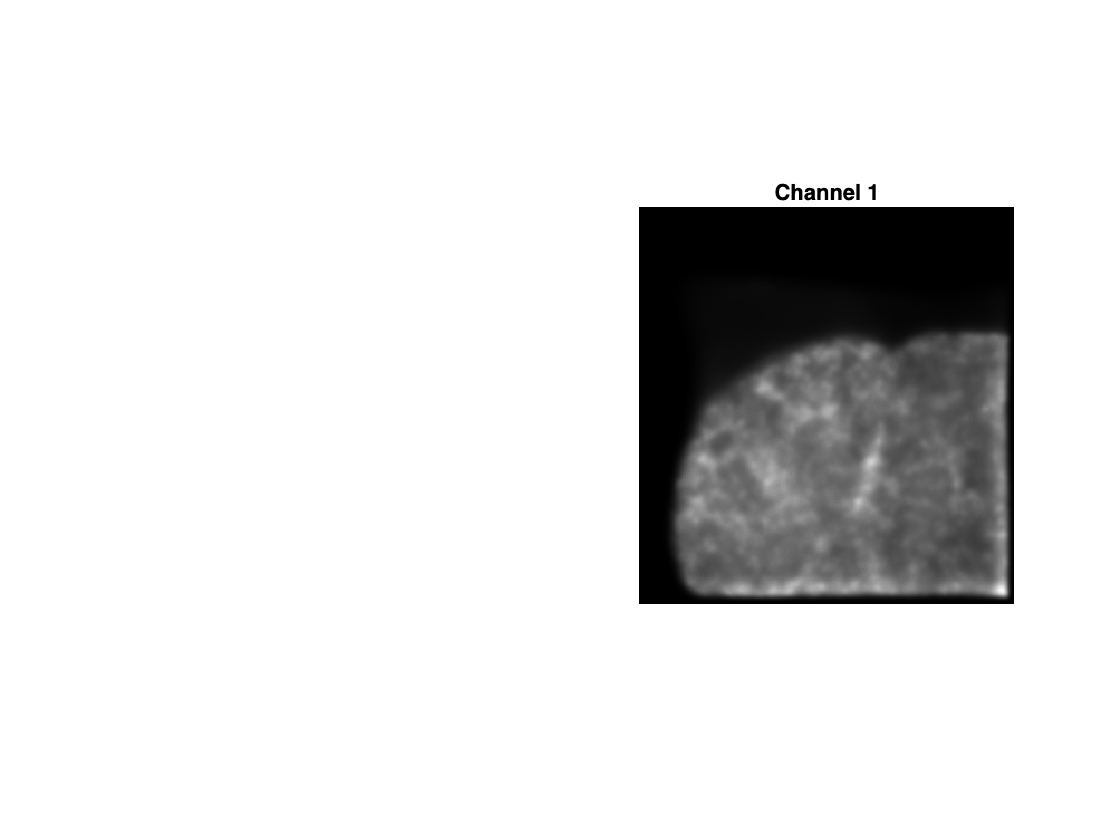

% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imagesc(channel1(:, :, 52));

% Añadir título
title('Channel 1');

% Desactivar los ejes
axis off;

### Canal 2

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath2 = '/Users/yi/TFGNotebook/CElegans-DAPI';
psfPath2 = '/Users/yi/TFGNotebook/PSF-CElegans-DAPI';

% Cargar las imágenes en una matriz 3D
image_stack2 = load_image_stack(imagePath2);
psf_stack2 = load_image_stack(psfPath2);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack2 = image_stack2(1:356, 1:336, :);
psf_stack2 = psf_stack2(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack2));

   356   336   104



disp(size(psf_stack2));

   305   305   104



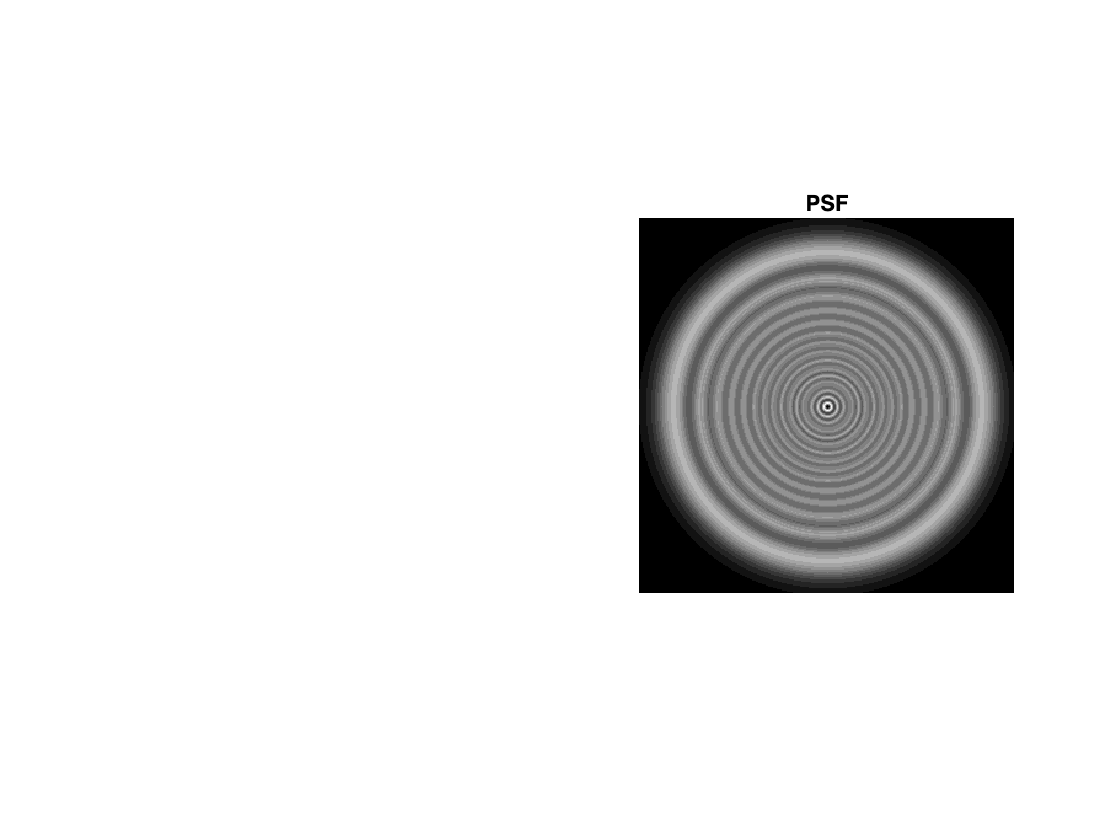


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack2(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel2 = DL2.RL(image_stack2, psf_stack2, 50,'-out stack');

Log   	 97,00 us 	  743,5Mb  	 Create Live Real Signal 


% Seleccionar el stack 52
stack_52 = channel2(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized, '50iter_DL2Channel2.png');
disp('Imagen guardada como stack_52_outputChannel2.png');

Imagen guardada como stack_52_outputChannel2.png


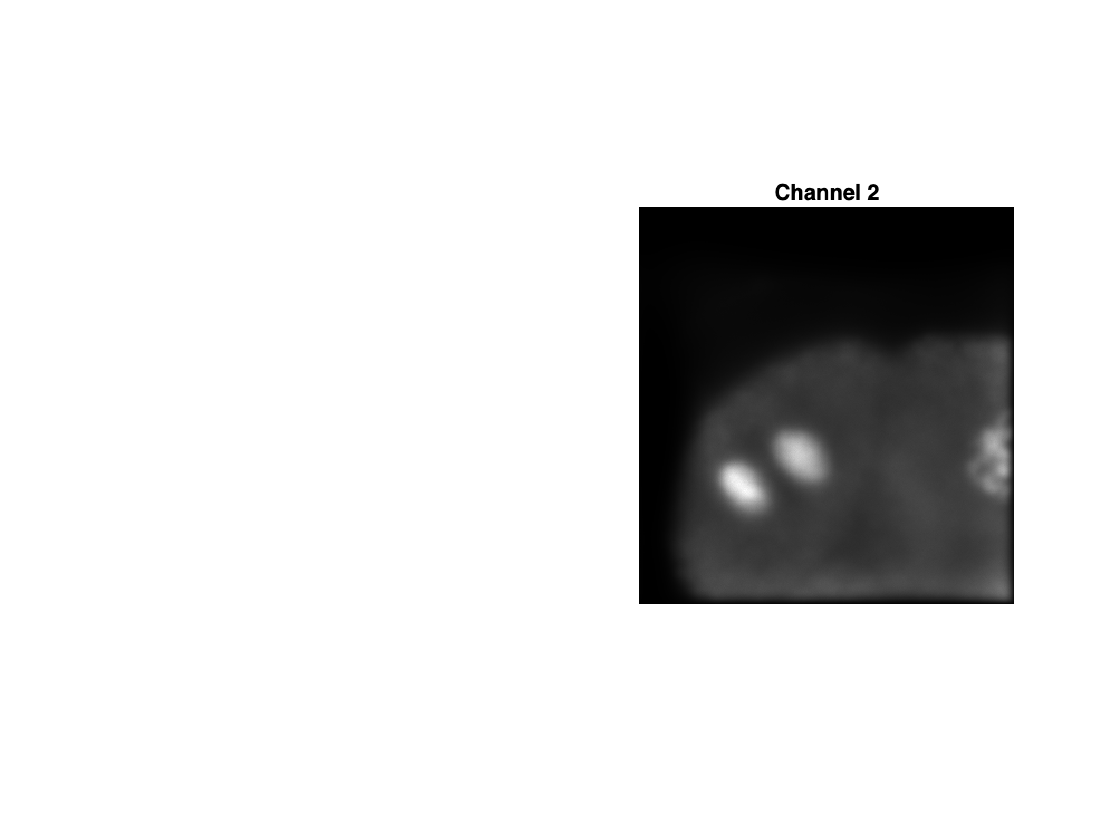


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel2(:, :, 52),[]);

% Añadir título
title('Channel 2');

% Desactivar los ejes
axis off;

### Canal 3

% Ruta a la carpeta que contiene las imágenes Z-stack
imagePath3 = '/Users/yi/TFGNotebook/CElegans-FITC';
psfPath3 = '/Users/yi/TFGNotebook/PSF-CElegans-FITC';

% Cargar las imágenes en una matriz 3D
image_stack3 = load_image_stack(imagePath3);
psf_stack3 = load_image_stack(psfPath3);

% Recortar las matrices 3D a las dimensiones especificadas
image_stack3 = image_stack3(1:356, 1:336, :);
psf_stack3 = psf_stack3(204:508,184:488, :);

% Verificar las dimensiones de las matrices 3D
disp(size(image_stack3));

   356   336   104



disp(size(psf_stack3));

   305   305   104



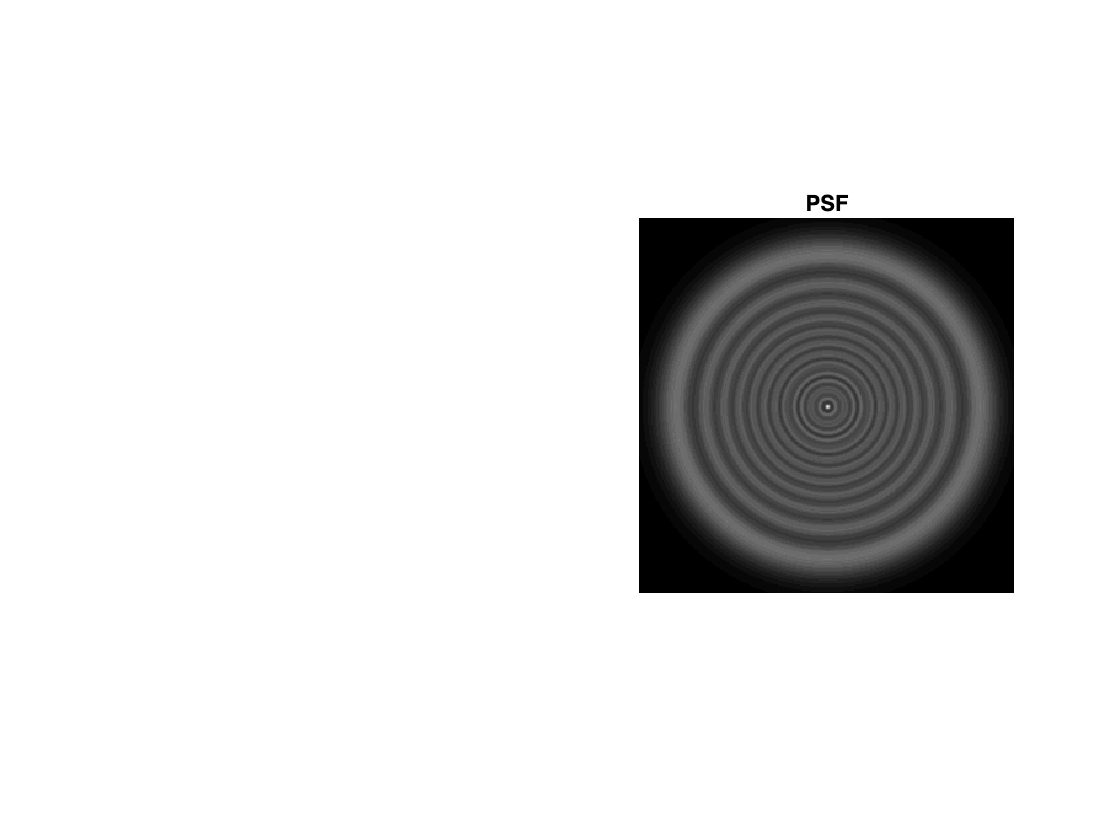



% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(psf_stack3(:, :, 1),[]);

% Añadir título
title('PSF');

% Desactivar los ejes
axis off;

channel3 = DL2.RL(image_stack3, psf_stack3, 50,'-out stack');

Log   	 84,96 us 	 1260,6Mb  	 Create Live Real Signal 


% Seleccionar el stack 52
stack_52 = channel3(:,:,52);

% Normalizar los valores para que estén en el rango [0, 255] si es necesario
stack_52_normalized = uint8(255 * mat2gray(stack_52)); % Escala a rango 0-255 y convierte a uint8

% Guardar el stack como archivo PNG
imwrite(stack_52_normalized, '50iter_DL2Channel3.png');
disp('Imagen guardada como stack_52_outputChannel3.png');

Imagen guardada como stack_52_outputChannel3.png


% Crear una nueva figura
figure;

% Seleccionar el subplot 1x2, posición 2
subplot(1, 2, 2);

% Mostrar la imagen del stack psf_stack en la primera capa
imshow(channel3(:, :, 52),[]);

% Añadir título
title('Channel 3');

% Desactivar los ejes
axis off;

### Combinación de canales

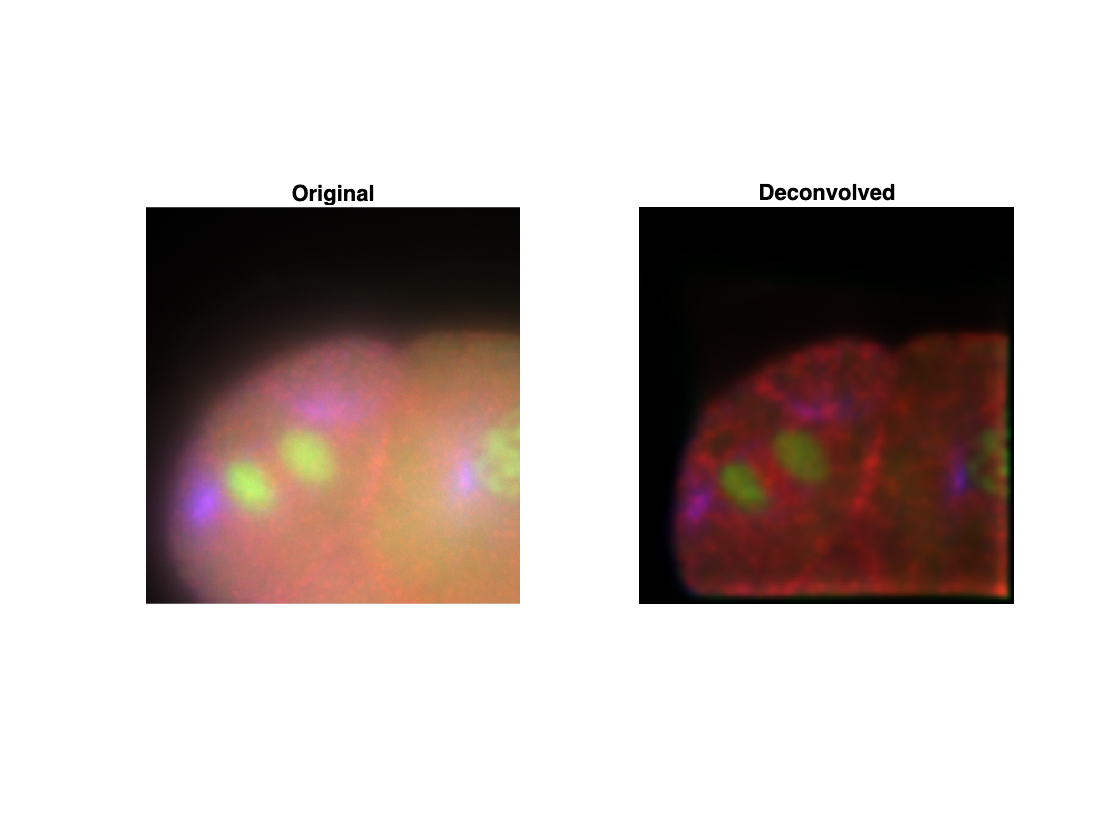

function normalized_image = normalize(image)
    min_val = double(min(image(:)));  % Convertir a double para evitar problemas con uint16
    max_val = double(max(image(:)));
    if min_val == max_val
        normalized_image = zeros(size(image), 'like', image);  % Usar el mismo tipo de datos
    else
        normalized_image = (double(image) - min_val) / (max_val - min_val);
    end
end

% Normalizar los canales (opcional, pero recomendado)
deconvolved_stack_R = normalize(channel1);
deconvolved_stack_G = normalize(channel2);
deconvolved_stack_B = normalize(channel3);

% Combinar los tres canales en una sola matriz 4D (altura, ancho, profundidad, canales)
deconvolved_stack_color = cat(4, deconvolved_stack_R, deconvolved_stack_G, deconvolved_stack_B);



% Visualizar un plano específico de la imagen deconvolucionada en color
figure;

subplot(1, 2, 1);
original_image_R = normalize(image_stack1(:, :, 52));
original_image_G = normalize(image_stack2(:, :, 52));
original_image_B = normalize(image_stack3(:, :, 52));
original_image_color = cat(3, original_image_R, original_image_G, original_image_B);
imshow(original_image_color);
title('Original');
axis off;

subplot(1, 2, 2);
deconvolved_image_color = squeeze(deconvolved_stack_color(:, :, 52, :));  % Convertir 4D a 3D para mostrar
imshow(deconvolved_image_color);
title('Deconvolved');
axis off;


% Guardar imagen PNG
imwrite(deconvolved_image_color, 'deconvolved_CElegans_deconvolutionLAB.png');

save('DL2_testimage.mat', 'testresult');
